sound analysis

[x,fs] = audioread("cleandata/belly_pain/belly_pain (4).wav");

% audioIn = x
% x = x(: , 1);
% N = length(x);
% t = (0:N-1)/fs
% plot(t,x)
% grid on 
% xlabel('Time(x)')
% ylabel('Amp')
% title('signal in time domain')

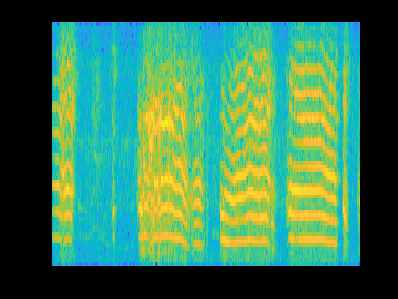

spectrogram(x,128,120,128,fs,'yaxis') 
set(gca,'Visible','off');
colorbar('off');
exportgraphics(gca,'test.png','BackgroundColor','none')

%saveas(gcf,"test1.png");

% s = spectrogram(x,128,120,128,fs,'yaxis')
% imwrite(s),"file_new.png")

% melSpectrogram(audioIn,fs)

matlabroot

mfcc(audioIn,fs)

cd (fullfile(matlabroot,'extern','engines','python'))
system('python setup.py install')